# Neural network based adaptive control of nonlinear uncertain systems

## *Input saturation constraint and neural network based observer*

clear; clc;

## Simulation initialization

**Time interval initialization:**

Ts = 0.005;
t = 0:Ts:100;

**Define the desired trajector using a *****smooth function*****:**

yd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

**Model related initialization:**

x0 = [0.5; 0.5];
zeta0 = [0; 0];
mu = 0.1;
Ac = -eye(2);

**Input control signal constraint bounds:**

input_upper_bound = 2;
input_lower_bound = -2;

**Normal form matrices:**

A = [0 1; 0 0];
B = [0; 1];
C = [1; 0];

**Controller neural network parameters:**

input_size_cnn = 4;
hidden_layer_size_cnn = 20;

**Controller neural network hyperparameters:**

K = -eye(2);
h = -[10; 10]; 
lr_c = 0.45;
gamma_c = 0.0001;

**Controller neural network weights initialization:**

Vc = rands(hidden_layer_size_cnn, input_size_cnn);
Wc = rands(1, hidden_layer_size_cnn);

**Observer gain and initialization **

observer_poles = [-7 -8];
G = place(A', C, observer_poles)'; %G = [15; 15]; %G = [14;49];
Obs = [C'; C'*Ac];
Aocl = A - G*C';

**Observer neural network parameters:**

input_size_onn = 3;
hidden_layer_size_onn = 20;

**Observer neural network hyperparameters:**

lr_o = 30;
gamma_o = 0.003;

**Observer neural network wights initialization:**

Vo = rands(hidden_layer_size_onn, input_size_onn);
Wo = rands(1, hidden_layer_size_onn);

**Simulation initialization:**

x = zeros(2, length(t));
zeta = zeros(2, length(t));
xi_hat = zeros(2, length(t));
x(:, 1) = x0;
zeta(:, 1) = zeta0;

u = zeros(length(t), 1);
e = zeros(2, length(t));
y_e = zeros(length(t), 1);
r = zeros(length(t), 1);
Lambda = 1.6;

changeMoment = ceil(length(t)/2);

## Numeric simulation

x_cnn = [x(1, 1) - yd(1, 1); xi_hat(2, 1) - yd(2, 1); yd(:, 1)] - [zeta(:, 1); 0; 0];
[u(1), delta_u] = control_saturation(-Wc*tanh(Vc*x_cnn), input_lower_bound, input_upper_bound);

for i = 1:length(t) - 1
    if i == changeMoment
        mu = mu + 2;
    end
    
    % compute current tracking error
    e(:, i) = [x(1, i); xi_hat(2, i)] - yd(:, i) - zeta(:, i);
    y_e(i) = C'*x(:, i) - C'*xi_hat(:, i);
    
    % filtered modified tracking error
    r(i) = [Lambda 1]*e(:, i);
    
    % observer neural network input
    x_onn = [x(1, i); xi_hat(2, i); u(i)];
    % controller neural network input
    x_cnn = [x(1, i) - yd(1, i); xi_hat(2, i) - yd(2, i); yd(:, i)] - [zeta(:, i); 0; 0];
    
    if delta_u >= input_upper_bound
        delta_u = 1;
    else
        if delta_u <= input_lower_bound
            delta_u = 1;
        else
            delta_u = 0;
        end
    end
    
    % backpropagation
    dWo = (y_e(i)*C'*inv(Aocl)*B)'*tanh(Vo*x_onn)';
    dVo = (y_e(i)*C'*inv(Aocl)*B*Wo*(eye(hidden_layer_size_onn) - diag(tanh(Vo*x_onn).^2)))'*x_onn';
    dWc = r(i)*[Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u)*tanh(Vc*x_cnn)';
    dVc = r(i)*([Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u)*Wc*(eye(hidden_layer_size_cnn) - diag(tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    Wo = Wo + Ts*(-lr_o*dWo - gamma_o*norm(y_e(i))*Wo);
    Vo = Vo + Ts*(-lr_o*dVo - gamma_o*norm(y_e(i))*Vo);
    Wc = Wc + Ts*(-lr_c*dWc - gamma_c*norm(r(i))*Wc - gamma_c*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr_c*dVc - gamma_c*norm(r(i))*Vc - gamma_c*norm(zeta(:, i))*Vc);
    
    % controller neural network inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    % observer neural network inference
    H_hat = Wo*tanh(Vo*x_onn);
    
    % saturation effect applied on the control signal
    [u(i), delta_u] = control_saturation(u(i), input_lower_bound, input_upper_bound);
       
    x(:, i + 1) = x(:, i)+ Ts*van_der_pol_derivative(x(:, i), u(i), mu);% + [0.001 ; 0.001];
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
    xi_hat(:, i + 1) = xi_hat(:, i) + Ts*observer_derivative(xi_hat(:, i), A, B, C, G, C'*x(:, i), H_hat);
end

## Result visualization

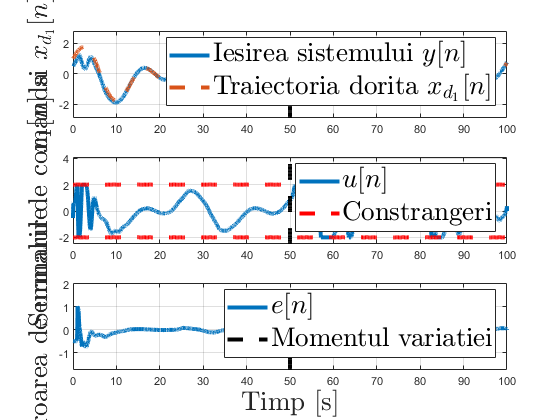

q = -10:Ts:10;
lineWidth = 3;
fontSize = 20;

figure,
subplot(3, 1, 1);
plot(t, x(1, :), "LineWidth", lineWidth); hold on; grid;
plot(t, yd(1, :), "--", "LineWidth", lineWidth);
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("$x_1[n]$ si $x_{d_1}[n]$", "Interpreter","latex", 'FontSize', fontSize);
legend("Iesirea sistemului $y[n]$",  "Traiectoria dorita $x_{d_1}[n]$", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) min(x(1, :))-1 max(x(1, :))+1])

subplot(3, 1, 2);
plot(t, u, "LineWidth", lineWidth); grid; hold on;
plot(t, input_upper_bound*ones(size(t)), "Color", "Red", "LineStyle","--", "LineWidth", lineWidth);
plot(t, input_lower_bound*ones(size(t)), "Color", "Red", "LineStyle","--", "LineWidth", lineWidth);
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("Semnalul de comanda", "Interpreter","latex", 'FontSize', fontSize);
legend("$u[n]$", "Constrangeri", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) input_lower_bound-0.5 input_upper_bound + 2.1])

subplot(3, 1, 3);
plot(t, e(1, :), "LineWidth", lineWidth); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("Timp [s]", "Interpreter","latex", 'FontSize', fontSize);
ylabel("Eroarea de urmarire", "Interpreter","latex", 'FontSize', fontSize);
legend("$e[n]$", "Momentul variatiei", "Interpreter", "Latex", "Location","northeast", 'FontSize', fontSize);
axis([0 t(end) min(e(1, :)) - 1 max(e(1, :)) + 1])

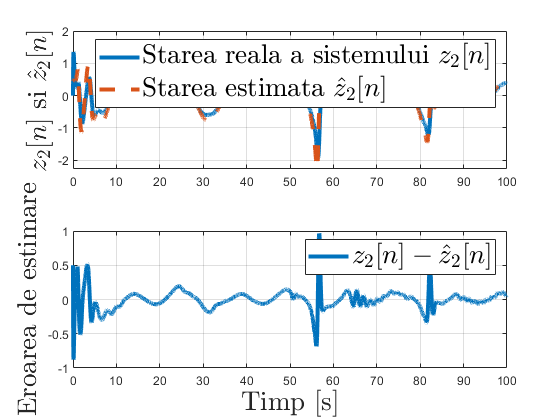


figure,
subplot(2, 1, 1);
plot(t, xi_hat(2, :), "LineWidth", lineWidth); grid; hold on;
plot(t, x(2, :), '--', "LineWidth", lineWidth);
ylabel("$z_2[n]$ si $\hat{z}_2[n]$", "Interpreter","latex", "FontSize", fontSize);
legend("Starea reala a sistemului $z_2[n]$", "Starea estimata $\hat{z}_2[n]$", "Interpreter","latex", ...
    "Location", "northeast", "FontSize", fontSize);

subplot(2, 1, 2);
plot(t, x(2, :) - xi_hat(2, :), "LineWidth", lineWidth); grid;
xlabel("Timp [s]", "Interpreter","latex", "FontSize", fontSize);
ylabel("Eroarea de estimare", "Interpreter","latex", "FontSize", fontSize);
legend("$z_2[n] - \hat{z}_2[n]$", "Interpreter","latex", ...
    "Location", "northeast", "FontSize", fontSize);